# Random Sampling

Code to randomly sample data from a ground truth data set and use Kriging to create predictions for the remaining data of each sample set. This code uses a smaller subsection of the groundtruth data, a 128x128 matrix taken from the upper left-hand corner.

### Step 1: Import and Process Data for Sampling

Load KCS_image_linear, x_grid, and y_grid from the Fig11b_linear.mat file

- x_grid: 256x1 array of x coordinates for KCS_image_linear

- y_grid: 256x1 array of y coordinates for KCS_image_linear

- KCS_image_linear: 256x256 array of data values

load Fig11b_linear

Convert the KCS_image_linear field to dB and take left, top corner 128x128 matrix

KCS_image = 20*log10(KCS_image_linear);
KCS_image = KCS_image(1:128, 1:128);

Create matrix of x, y, and z coordinates

xy_grid = gridsamp([110 -125;235 0], 128);
xyz_values = [xy_grid KCS_image(:)];

Plot the original field

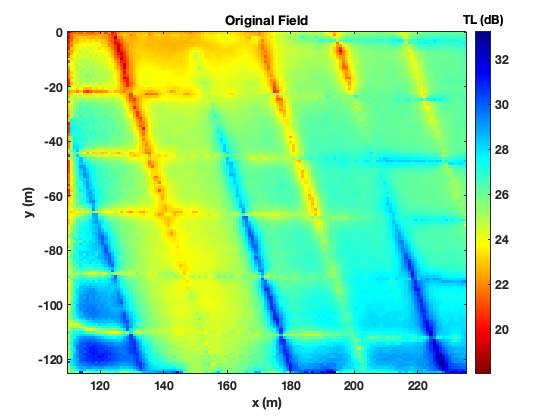

figure(1)
h = imagesc(xy_grid(:,1), xy_grid(:,2), KCS_image);
title('Original Field')
xlabel( 'x (m)')
ylabel('y (m)')
set(gca,'ydir','normal')
shading interp
colorbar
colormap(flipud(jet))
set(gca, 'FontSize',12,'FontWeight','bold')
h=colorbar; set(h, 'FontSize',12,'FontWeight','bold');
title(h, 'TL (dB)')

### Step 2: Select Sampling Rate and Data Points

Sampling Rate

SAMP_RATE = .6

SAMP_RATE = 0.3000

Create Data Set Using Provided Sampling Rate

xyz = datasample(xyz_values, round(16384*SAMP_RATE), 'Replace', false);
xyz = sortrows(xyz, [1 2]);

### Step 3: Plot Sampled Points

Format data to plot

xyz_full = [xy_grid NaN(16384, 1)];
xyz_full(ismembertol(xyz_full(:,1:2), xyz(:,1:2),'ByRows',true), 3) = xyz(:, 3);
z = reshape(xyz_full(:,3),128,128);

Plot all sampled points

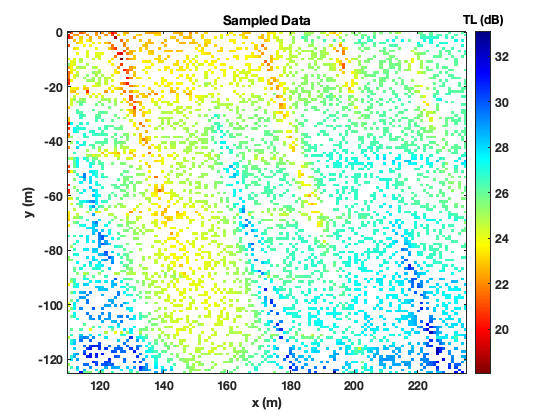

figure(2)
h = imagesc(xy_grid(:,1), xy_grid(:,2), z);
set(h,'alphadata',~isnan(z))
title('Sampled Data')
xlabel( 'x (m)')
ylabel('y (m)')
set(gca,'ydir','normal')
shading interp
colorbar
colormap(flipud(jet))
set(gca, 'FontSize',12,'FontWeight','bold')
h=colorbar; set(h, 'FontSize',12,'FontWeight','bold');
title(h, 'TL (dB)')
print('figure2', '-dpng');

### Step 4: Graph Semivariogram for Data Points and Select Kriging Model

Graph the variogram for the sampled data

% d = variogram(xyz(:,1:2), xyz(:,3), 'plotit', true)

### Step 5: Create Kriging Model

Create kriging model for sampled data using dacefit with a gaussian model

[dmodel, perf] = dacefit(xyz(:,1:2), xyz(:,3), @regpoly0, @corrgauss, 1);

### Step 6: Create Kriging Predictions and Graph

Predict all data points using the kriging model for the data

[YX, MSE] = predictor(xy_grid, dmodel);
YX = reshape(YX, 128, 128);

Plot all data points: sampled and predicted

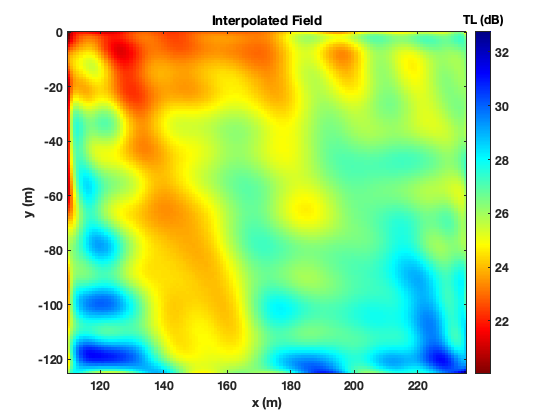

figure(3)
h = imagesc(xy_grid(:,1), xy_grid(:,2), YX);
title('Interpolated Field')
xlabel( 'x (m)')
ylabel('y (m)')
set(gca,'ydir','normal')
shading interp
colorbar
colormap(flipud(jet))
set(gca, 'FontSize',12,'FontWeight','bold')
h=colorbar; set(h, 'FontSize',12,'FontWeight','bold');
title(h, 'TL (dB)')
print('figure3', '-dpng');

### Step 7: Calculate PSNR

Calculate PSNR using the equation:

- PSNR = 20 * log10 (max field value / root mean square error)

E    = KCS_image - YX;
SQE  = E.^2;
MSE2  = mean(SQE(:));
RMSE = sqrt(MSE2);
max_val = max(KCS_image(:));
PSNR = 20*log10(max_val/RMSE)

PSNR = 34.6820